%% UR3 + własne TCP + chwytak + workspace
clear; clc; close all;

%% 1. Wczytanie robota

robot = loadrobot("universalUR3", ...
    "DataFormat","row", ... 
    "Gravity",[0 0 -9.81]);

disp("Body names:");

Body names:


disp(robot.BodyNames');

    {'base_link'     }
    {'base'          }
    {'shoulder_link' }
    {'upper_arm_link'}
    {'forearm_link'  }
    {'wrist_1_link'  }
    {'wrist_2_link'  }
    {'wrist_3_link'  }
    {'ee_link'       }
    {'tool0'         }




% Konfiguracja testowa
q = [0 -pi/2 0 0 -pi/2 0];

%% 2. Nazwa członu, do którego dodajemy narzędzie

parentBodyName = "tool0";

if ~any(strcmp(robot.BodyNames, parentBodyName))
    warning("Nie znaleziono body '%s'. Używam ostatniego body w modelu.", parentBodyName);
    parentBodyName = robot.BodyNames{end};
end

fprintf("Narzędzie zostanie dodane do body: %s\n", parentBodyName);

Narzędzie zostanie dodane do body: tool0



%% 3. Dane TCP względem flanszy/tool0

% Dane do wpisania w pendant UR:
% X  =    0 mm
% Y  = -290 mm
% Z  =  260 mm
% RX = 0
% RY = 0
% RZ = 0

tcp_x =  0.000;
tcp_y = -0.290;
tcp_z =  0.260;

tcp_rx = 0;
tcp_ry = 0;
tcp_rz = 0;

%% 4. Wymiary chwytaka [m]

% ---------------------------------------------------------
% Belka pionowa
% ---------------------------------------------------------
beam_len  = 0.31;       % 31 cm
beam_side = 0.015;      % 1.5 cm x 1.5 cm

% Pręt
rod_len    = 0.25;      % 25 cm
rod_radius = 0.003;     % średnica 0.6 cm -> promień 0.3 cm

% Wysokość mocowania pręta na belce
% Mierzone od dołu belki.
rod_height_from_bottom = 0.29;   % 29 cm od dołu belki

% Z tego wynika, że nad prętem zostaje:
attach_from_top = beam_len - rod_height_from_bottom;

fprintf("Pręt wychodzi %.1f cm poniżej górnego końca belki.\n", attach_from_top*100);

Pręt wychodzi 2.0 cm poniżej górnego końca belki.



% Widły
fork_len        = 0.035;     % 3.5 cm
fork_gap        = 0.030;     % rozstaw końcówek 3 cm
fork_width      = 0.004;     % szerokość jednej szczęki
fork_thick      = 0.004;     % grubość jednej szczęki
fork_tilt_deg   = 15;        % pochylenie wideł

% Bloczek przy flanszy
flange_block_thick = 0.020;  % 2 cm
flange_block_side  = 0.055;  % przyjęte pomocniczo 5.5 cm

% Bloczek 90 stopni belka-pręt
joint_block_side = 0.020;    % 2 cm

%% 5. Transformacja flansza -> TCP

% Orientacja TCP jest zerowa, więc wystarczy translacja.
% Gdybyś kiedyś miał niezerowe RX RY RZ, trzeba złożyć rotację z wektora rotacji.
T_flange_tcp = trvec2tform([tcp_x tcp_y tcp_z]);

%% 6. Utworzenie body narzędzia

tool = rigidBody("custom_tcp");
toolJoint = rigidBodyJoint("custom_tcp_fixed","fixed");

setFixedTransform(toolJoint, T_flange_tcp);
tool.Joint = toolJoint;

%% 7. Geometria chwytaka względem TCP

% =========================================================
% Przyjęty lokalny układ TCP:
%
% - TCP jest na końcu pręta, przy mocowaniu wideł.
% - Pręt idzie od TCP do belki w kierunku lokalnym -Z.
% - Widły idą zasadniczo w dół, czyli w kierunku lokalnym +Y.
% - Belka jest pionowa, jej długość jest w osi lokalnej Y.
% - Pręt wychodzi z belki 29 cm od dołu, czyli 2 cm od góry.
%
% Wszystkie collision obiekty są definiowane względem custom_tcp.
% =========================================================

%% 7.1 Pręt

% Punkt końca pręta przy belce, liczony względem TCP.
p_rod_start_tcp = [0 0 -rod_len];

% Cylinder jest domyślnie wzdłuż osi Z.
% Środek pręta jest w połowie długości między TCP a belką.
T_rod = trvec2tform([0 0 -rod_len/2]);

rodCollision = collisionCylinder(rod_radius, rod_len);
addCollision(tool, rodCollision, T_rod);

%% 7.2 Belka pionowa

% Chcemy, żeby pręt wychodził z przedniej ścianki belki.
% Lokalny punkt mocowania na belce względem jej środka:
%
% y = -beam_len/2 + attach_from_top
% ponieważ góra belki jest przy y = -beam_len/2,
% a pręt jest attach_from_top poniżej góry.
%
% z = +beam_side/2
% czyli przednia ścianka belki, od strony TCP.

p_attach_beam_local = [ ...
    0, ...
   -beam_len/2 + attach_from_top, ...
    beam_side/2];

% Szukamy środka belki tak, aby punkt mocowania pokrył się
% z początkiem pręta.
p_beam_center_tcp = p_rod_start_tcp - p_attach_beam_local;

T_beam = trvec2tform(p_beam_center_tcp);

beamCollision = collisionBox(beam_side, beam_len, beam_side);
addCollision(tool, beamCollision, T_beam);

%% 7.3 Bloczek 90 stopni na połączeniu belka-pręt

% Mały bloczek w miejscu wyjścia pręta z belki.
% To jest uproszczona reprezentacja połączenia 90 stopni.
T_joint_block = trvec2tform(p_rod_start_tcp);

jointBlockCollision = collisionBox(joint_block_side, joint_block_side, joint_block_side);
addCollision(tool, jointBlockCollision, T_joint_block);

%% 7.4 Bloczek przy flanszy

% Ponieważ custom_tcp jest odsunięty od tool0 o [tcp_x tcp_y tcp_z],
% położenie flanszy względem TCP to w przybliżeniu:
p_flange_tcp = [-tcp_x, -tcp_y, -tcp_z];

% Uproszczony bloczek przy flanszy.
% Jeżeli przeszkadza w wizualizacji/kolizjach, można go zakomentować.
T_flange_block = trvec2tform(p_flange_tcp);

flangeBlockCollision = collisionBox(flange_block_side, flange_block_thick, flange_block_side);
addCollision(tool, flangeBlockCollision, T_flange_block);

%% 7.5 Widły

% Widły mają kształt V.
% Rozwarcie końcówek wynosi fork_gap.
% Długość każdej szczęki wynosi fork_len.

% Kąt rozwarcia jednej szczęki względem osi środkowej.
fork_open = atan((fork_gap/2) / fork_len);

% Pochylenie wideł.
% Jeżeli w wizualizacji pochylą się w złą stronę,
% zmień znak przy fork_tilt_deg.
fork_tilt = deg2rad(-fork_tilt_deg);

R_tilt = axang2tform([1 0 0 fork_tilt]);

R_open_left  = axang2tform([0 0 1  fork_open]);
R_open_right = axang2tform([0 0 1 -fork_open]);

% Jedna szczęka jako cienki box.
% Długość boxa jest w osi Y.
forkCollision = collisionBox(fork_width, fork_len, fork_thick);

% Środek szczęki jest w połowie długości od TCP.
T_fork_left = R_tilt * R_open_left * trvec2tform([0, fork_len/2, 0]);
addCollision(tool, forkCollision, T_fork_left);

T_fork_right = R_tilt * R_open_right * trvec2tform([0, fork_len/2, 0]);
addCollision(tool, forkCollision, T_fork_right);

%% 8. Dodanie narzędzia do robota

addBody(robot, tool, parentBodyName);

%% 9. Wizualizacja robota z chwytakiem

figure('Color','w');
show(robot, q, ...
    "Frames","on", ...
    "Collisions","on", ...
    "Visuals","on");

axis equal;
grid on;
view(135, 25);
title("UR3 z własnym TCP i modelem chwytaka");

exportgraphics(gcf, "model_UR3_chwytak.png", "Resolution", 300);

%% 10. Wydruk TCP do teach pendanta

tcp_xyz_m = tform2trvec(T_flange_tcp);

R_flange_tcp = tform2rotm(T_flange_tcp);
axang = rotm2axang(R_flange_tcp);

% UR używa wektora rotacji:
% [rx ry rz] = oś * kąt
tcp_rvec_rad = axang(1:3) * axang(4);

fprintf("\n========================================\n");

fprintf("TCP do wpisania w UR / PolyScope\n");

TCP do wpisania w UR / PolyScope


fprintf("========================================\n");


fprintf("Format URScript:\n");

Format URScript:


fprintf("p[%.6f, %.6f, %.6f, %.6f, %.6f, %.6f]\n", ...
    tcp_xyz_m(1), tcp_xyz_m(2), tcp_xyz_m(3), ...
    tcp_rvec_rad(1), tcp_rvec_rad(2), tcp_rvec_rad(3));

p[0.000000, -0.290000, 0.260000, 0.000000, 0.000000, 0.000000]



fprintf("\nPozycja w milimetrach:\n");


Pozycja w milimetrach:


fprintf("X  = %.1f mm\n", tcp_xyz_m(1)*1000);

X  = 0.0 mm


fprintf("Y  = %.1f mm\n", tcp_xyz_m(2)*1000);

Y  = -290.0 mm


fprintf("Z  = %.1f mm\n", tcp_xyz_m(3)*1000);

Z  = 260.0 mm



fprintf("\nRotacja jako wektor rotacji:\n");


Rotacja jako wektor rotacji:


fprintf("RX = %.6f rad\n", tcp_rvec_rad(1));

RX = 0.000000 rad


fprintf("RY = %.6f rad\n", tcp_rvec_rad(2));

RY = 0.000000 rad


fprintf("RZ = %.6f rad\n", tcp_rvec_rad(3));

RZ = 0.000000 rad



%% 11. Odczyt pozycji TCP względem base dla konfiguracji q

T_base_tcp = getTransform(robot, q, "custom_tcp");

disp("Transformacja base -> custom_tcp:");

Transformacja base -> custom_tcp:


disp(T_base_tcp);

    0.0000   -1.0000    0.0000    0.3754
   -1.0000    0.0000    0.0000    0.1124
   -0.0000   -0.0000   -1.0000    0.2669
         0         0         0    1.0000




tcp_position_base = tform2trvec(T_base_tcp);

disp("Pozycja TCP względem base [m]:");

Pozycja TCP względem base [m]:


disp(tcp_position_base);

    0.3754    0.1124    0.2669




%% 12. Test kolizji

[isColliding, sepDist, witnessPts] = checkCollision(robot, q, ...
    "IgnoreSelfCollision","on");

fprintf("Czy wykryto kolizję? %d\n", isColliding);

Czy wykryto kolizję? 0



%% 13. Punkty charakterystyczne chwytaka względem TCP

% Końce wideł w lokalnych układach boxów.
% Box szczęki ma długość fork_len w osi Y,
% więc koniec szczęki jest w +fork_len/2 od środka boxa.

p_left_tip_localBox  = [0; fork_len/2; 0; 1];
p_right_tip_localBox = [0; fork_len/2; 0; 1];

% Końce wideł względem TCP
p_left_tip_tcp  = T_fork_left  * p_left_tip_localBox;
p_right_tip_tcp = T_fork_right * p_right_tip_localBox;

% Środek między końcówkami wideł
p_center_tip_tcp = 0.5 * (p_left_tip_tcp + p_right_tip_tcp);

disp("Koniec lewej szczęki względem TCP [m]:");

Koniec lewej szczęki względem TCP [m]:


disp(p_left_tip_tcp(1:3).');

   -0.0138    0.0311   -0.0083




disp("Koniec prawej szczęki względem TCP [m]:");

Koniec prawej szczęki względem TCP [m]:


disp(p_right_tip_tcp(1:3).');

    0.0138    0.0311   -0.0083




disp("Środek końcówek wideł względem TCP [m]:");

Środek końcówek wideł względem TCP [m]:


disp(p_center_tip_tcp(1:3).');

         0    0.0311   -0.0083




%% 14. Workspace z losowych konfiguracji i filtrem orientacji chwytaka

% =========================================================
% Ta wersja bazuje na randomConfiguration(robot), ale nie
% wymaga identycznej orientacji TCP.
%
% Warunki:
% - lokalna oś wideł ma być skierowana prawie pionowo w dół,
% - lokalna oś pręta ma być prawie pozioma,
% - punkt roboczy chwytaka ma być nad stołem,
% - punkt roboczy chwytaka nie może być wyżej niż pozycja q_ref.
% =========================================================

q_ref = [0 -pi/2 0 0 -pi/2 0];

% Pozycja referencyjna, czyli maksymalne sensowne wychylenie
T_ref = getTransform(robot, q_ref, "custom_tcp");
p_ref_center = T_ref * p_center_tip_tcp;
z_max_ref = p_ref_center(3);

z_table = 0.0;
z_margin = 0.02;
z_max_allowed = z_max_ref + z_margin;

fprintf("\n========================================\n");

fprintf("Workspace z randomConfiguration + filtr osi\n");

Workspace z randomConfiguration + filtr osi


fprintf("========================================\n");

fprintf("Z table      = %.3f m\n", z_table);

Z table      = 0.000 m


fprintf("Z max q_ref  = %.3f m\n", z_max_ref);

Z max q_ref  = 0.275 m


fprintf("Z max used   = %.3f m\n", z_max_allowed);

Z max used   = 0.295 m



% ---------------------------------------------------------
% Osie lokalne chwytaka
% ---------------------------------------------------------
% U Ciebie po zmianie wynik się poprawił, więc zostawiam -Y.
% Jeśli znowu kierunek będzie zły, zmień na [0; 1; 0].
local_down_axis = [0; -1; 0];

% Pręt/długa belka lokalnie idzie wzdłuż -Z
local_rod_axis = [0; 0; -1];

world_down = [0; 0; -1];
world_up   = [0; 0;  1];

% Tolerancje orientacji
% Większe wartości = więcej punktów, bardziej miękki filtr.
downTolDeg = 18;
rodTolDeg  = 18;

fprintf("downTolDeg = %.1f deg\n", downTolDeg);

downTolDeg = 18.0 deg


fprintf("rodTolDeg  = %.1f deg\n", rodTolDeg);

rodTolDeg  = 18.0 deg



% ---------------------------------------------------------
% Ile punktów chcemy zebrać
% ---------------------------------------------------------
targetValidPts = 20000;      % do testu 5000, do dokumentacji 20000-40000
maxAttempts    = 1500000;    % maksymalna liczba losowań

pts_center = zeros(targetValidPts,3);
pts_tcp    = zeros(targetValidPts,3);
Q_valid    = zeros(targetValidPts,6);

validCount = 0;
attempts = 0;

fprintf("Zbieranie punktów workspace...\n");

Zbieranie punktów workspace...



while validCount < targetValidPts && attempts < maxAttempts

    attempts = attempts + 1;

    qk = randomConfiguration(robot);

    T_base_tcp_k = getTransform(robot, qk, "custom_tcp");
    R_k = tform2rotm(T_base_tcp_k);

    % -----------------------------------------------------
    % Filtr 1: widły / pionowy element prawie pionowo w dół
    % -----------------------------------------------------
    down_axis_base = R_k * local_down_axis;
    down_axis_base = down_axis_base / norm(down_axis_base);

    c_down = dot(down_axis_base, world_down);
    c_down = max(-1, min(1, c_down));

    downErrDeg = rad2deg(acos(c_down));

    if downErrDeg > downTolDeg
        continue;
    end

    % -----------------------------------------------------
    % Filtr 2: pręt / belka prawie poziomo
    % -----------------------------------------------------
    rod_axis_base = R_k * local_rod_axis;
    rod_axis_base = rod_axis_base / norm(rod_axis_base);

    rodVerticalComponent = abs(dot(rod_axis_base, world_up));
    rodErrDeg = rad2deg(asin(max(-1, min(1, rodVerticalComponent))));

    if rodErrDeg > rodTolDeg
        continue;
    end

    % -----------------------------------------------------
    % Punkt roboczy chwytaka
    % -----------------------------------------------------
    p_center_base = T_base_tcp_k * p_center_tip_tcp;
    p_center_base = p_center_base(1:3).';

    % Nad stołem
    if p_center_base(3) < z_table
        continue;
    end

    % Nie wyżej niż q_ref
    if p_center_base(3) > z_max_allowed
        continue;
    end

    validCount = validCount + 1;

    pts_center(validCount,:) = p_center_base;
    pts_tcp(validCount,:)    = tform2trvec(T_base_tcp_k);
    Q_valid(validCount,:)    = qk;

    if mod(validCount, 1000) == 0
        fprintf("Zebrano %d / %d punktów, attempts = %d\n", ...
            validCount, targetValidPts, attempts);
    end
end

Zebrano 1000 / 20000 punktów, attempts = 94686
Zebrano 2000 / 20000 punktów, attempts = 184423
Zebrano 3000 / 20000 punktów, attempts = 275385
Zebrano 4000 / 20000 punktów, attempts = 364393
Zebrano 5000 / 20000 punktów, attempts = 456327
Zebrano 6000 / 20000 punktów, attempts = 547567
Zebrano 7000 / 20000 punktów, attempts = 643349
Zebrano 8000 / 20000 punktów, attempts = 733535
Zebrano 9000 / 20000 punktów, attempts = 831855
Zebrano 10000 / 20000 punktów, attempts = 921909
Zebrano 11000 / 20000 punktów, attempts = 1015790
Zebrano 12000 / 20000 punktów, attempts = 1105427
Zebrano 13000 / 20000 punktów, attempts = 1195245
Zebrano 14000 / 20000 punktów, attempts = 1287448
Zebrano 15000 / 20000 punktów, attempts = 1380432
Zebrano 16000 / 20000 punktów, attempts = 1469509



pts_center = pts_center(1:validCount,:);
pts_tcp    = pts_tcp(1:validCount,:);
Q_valid    = Q_valid(1:validCount,:);

fprintf("\nZakończono zbieranie punktów.\n");


Zakończono zbieranie punktów.


fprintf("Poprawne punkty: %d\n", validCount);

Poprawne punkty: 16321


fprintf("Liczba prób:     %d\n", attempts);

Liczba prób:     1500000


fprintf("Skuteczność:     %.3f %%\n", 100*validCount/attempts);

Skuteczność:     1.088 %



if validCount < 200
    error("Za mało punktów. Zwiększ downTolDeg/rodTolDeg albo maxAttempts.");
end
%% 15. Przybliżona maksymalna średnica ograniczonego workspace

fprintf("\n========================================\n");

fprintf("Przybliżona średnica ograniczonego obszaru roboczego\n");

Przybliżona średnica ograniczonego obszaru roboczego


fprintf("========================================\n");


% Żeby nie liczyć wszystkich odległości dla bardzo dużego N,
% wybieramy maksymalnie M punktów.
M = 5000;

numPts = size(pts_center, 1);

if numPts > M
    idx = randperm(numPts, M);
    pts_diam = pts_center(idx, :);
else
    pts_diam = pts_center;
end

D = pdist2(pts_diam, pts_diam);

[max_diameter_m, linearIdx] = max(D(:));
[iMax, jMax] = ind2sub(size(D), linearIdx);

p1 = pts_diam(iMax, :);
p2 = pts_diam(jMax, :);

fprintf("Przybliżona maksymalna średnica workspace:\n");

Przybliżona maksymalna średnica workspace:


fprintf("%.4f m\n", max_diameter_m);

1.6610 m



fprintf("\nCzyli w milimetrach:\n");


Czyli w milimetrach:


fprintf("%.1f mm\n", max_diameter_m * 1000);

1661.0 mm



fprintf("\nPunkt 1 [m]: X = %.3f, Y = %.3f, Z = %.3f\n", p1(1), p1(2), p1(3));


Punkt 1 [m]: X = -0.287, Y = -0.777, Z = 0.084


fprintf("Punkt 2 [m]: X = %.3f, Y = %.3f, Z = %.3f\n", p2(1), p2(2), p2(3));

Punkt 2 [m]: X = 0.425, Y = 0.722, Z = 0.000


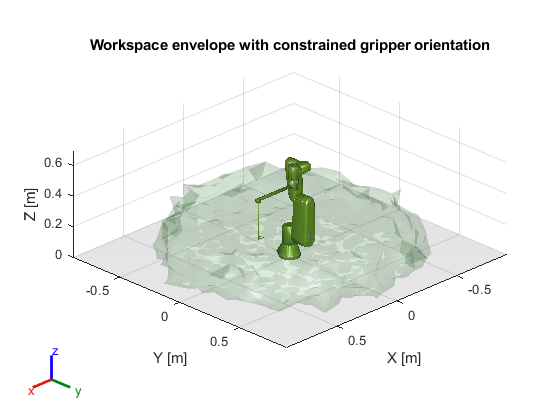


%% 16. Obwiednia workspace + robot z chwytakiem

try
    % ---------------------------------------------
    % Obwiednia zewnętrzna
    % ---------------------------------------------
    % 1.0 -> obwiednia bardziej wypukła
    % 0.8 -> dobry kompromis
    % 0.6 -> mocniej dopasowana
    shrinkFactor = 0.95;
    % Do obwiedni używamy podzbioru punktów, żeby boundary() nie liczyło zbyt długo.

    maxBoundaryPts = 20000;

    if size(pts_center,1) > maxBoundaryPts
        idxB = randperm(size(pts_center,1), maxBoundaryPts);
        pts_boundary = pts_center(idxB,:);
    else
        pts_boundary = pts_center;
    end
    K = boundary(pts_boundary(:,1), pts_boundary(:,2), pts_boundary(:,3), shrinkFactor);

    % ---------------------------------------------
    % Środek workspace
    % ---------------------------------------------
    workspace_center = mean(pts_center, 1);

    % Mała kula oznaczająca środek obszaru
    centerSphereRadius = 0.035;

    [sx, sy, sz] = sphere(30);
    sx = centerSphereRadius * sx + workspace_center(1);
    sy = centerSphereRadius * sy + workspace_center(2);
    sz = centerSphereRadius * sz + workspace_center(3);

    % ---------------------------------------------
    % Opcjonalny wewnętrzny rdzeń obszaru
    % ---------------------------------------------
    scaleInner = 0.50;
    pts_inner = workspace_center + scaleInner * (pts_center - workspace_center);

    K_inner = boundary(pts_inner(:,1), pts_inner(:,2), pts_inner(:,3), 0.8);

    % ---------------------------------------------
    % Rysunek
    % ---------------------------------------------
    figure('Color','w');
    ax = axes;
    hold(ax, 'on');

    % Robot z chwytakiem w pozycji referencyjnej
    show(robot, q_ref, ...
        "Parent", ax, ...
        "Frames", "off", ...
        "Visuals", "on", ...
        "Collisions", "on", ...
        "PreservePlot", false);

    hold(ax, 'on');

    % Zewnętrzna obwiednia workspace
    trisurf(K, ...
        pts_boundary(:,1), pts_boundary(:,2), pts_boundary(:,3), ...
        'Parent', ax, ...
        'FaceColor', [0.45 0.85 0.45], ...
        'FaceAlpha', 0.13, ...
        'EdgeColor', 'none');

    % % Środek workspace jako mała kula
    % surf(ax, sx, sy, sz, ...
    %     'FaceColor', [0.05 0.50 0.05], ...
    %     'FaceAlpha', 0.35, ...
    %     'EdgeColor', 'none');
    % 
    % % Punkt środka
    % plot3(ax, workspace_center(1), workspace_center(2), workspace_center(3), ...
    %     'o', ...
    %     'MarkerSize', 8, ...
    %     'MarkerFaceColor', [0 0.45 0], ...
    %     'MarkerEdgeColor', 'k');

    % % Linia maksymalnej średnicy
    % plot3(ax, ...
    %     [p1(1), p2(1)], ...
    %     [p1(2), p2(2)], ...
    %     [p1(3), p2(3)], ...
    %     'k-', ...
    %     'LineWidth', 1.6);
    % 
    % plot3(ax, p1(1), p1(2), p1(3), ...
    %     'ko', ...
    %     'MarkerSize', 5, ...
    %     'MarkerFaceColor', 'k');
    % 
    % plot3(ax, p2(1), p2(2), p2(3), ...
    %     'ko', ...
    %     'MarkerSize', 5, ...
    %     'MarkerFaceColor', 'k');
    % 
    % text(ax, ...
    %     mean([p1(1), p2(1)]), ...
    %     mean([p1(2), p2(2)]), ...
    %     mean([p1(3), p2(3)]), ...
    %     sprintf('D_{max} = %.2f m', max_diameter_m), ...
    %     'FontSize', 10, ...
    %     'FontWeight', 'bold');

    % ---------------------------------------------
    % Wygląd wykresu
    % ---------------------------------------------
    axis(ax, 'equal');
    grid(ax, 'on');

    xlabel(ax, 'X [m]');
    ylabel(ax, 'Y [m]');
    zlabel(ax, 'Z [m]');

    title(ax, "Workspace envelope with constrained gripper orientation");

    view(ax, 135, 25);

    camlight(ax, 'headlight');
    lighting(ax, 'gouraud');

    % ---------------------------------------------
    % Limity osi - bez obcinania obszaru
    % ---------------------------------------------
    x_all = [pts_center(:,1); pts_inner(:,1); workspace_center(1); 0];
    y_all = [pts_center(:,2); pts_inner(:,2); workspace_center(2); 0];
    z_all = [pts_center(:,3); pts_inner(:,3); workspace_center(3); z_table];

    pad = 0.08;

    xlim(ax, [min(x_all)-pad, max(x_all)+pad]);
    ylim(ax, [min(y_all)-pad, max(y_all)+pad]);

    % Odcinamy wszystko poniżej stołu
    zlim(ax, [z_table, 0.7]);

    % Dodatkowo płaszczyzna stołu
    xl = xlim(ax);
    yl = ylim(ax);

    [Xtable, Ytable] = meshgrid( ...
        linspace(xl(1), xl(2), 2), ...
        linspace(yl(1), yl(2), 2));

    Ztable = z_table * ones(size(Xtable));

    surf(ax, Xtable, Ytable, Ztable, ...
        'FaceColor', [0.85 0.85 0.85], ...
        'FaceAlpha', 0.20, ...
        'EdgeColor', 'none');

    % Żeby powierzchnia stołu nie zasłoniła robota
    uistack(findobj(ax, 'Type', 'Surface', 'FaceColor', [0.85 0.85 0.85]), 'bottom');

    ax.Clipping = 'on';

    exportgraphics(gcf, "workspace_constrained_orientation_robot.png", "Resolution", 300);

catch ME
    warning("Nie udało się narysować ograniczonej obwiedni workspace: %s", E.message);
end